## 1.基于柯西点的信任域算法

clc;
clf;
clear;
n = 10;         % n为Rosenbrock函数

x0 = 3 * (rand(n, 1) - 0.5);   % 产生(-1.5， 1.5)的n维变量
[~, ~, B] = Rosenbrock(x0);
try
    [~, flag] = chol(B);                    % 有可能初始值处Hessian矩阵不正当，不利于后续求解
catch ErrorInfo
    disp(ErrorInfo)
end
while flag > 0
    x0 = 3 * (rand(n, 1) - 0.5);
    [~, ~, B] = Rosenbrock(x0);
    [~, flag] = chol(B);
end
   
tic
[x, fx, count] = TrustRegion(@Rosenbrock, @CauchyPoint, x0, 2, 0.1, 1e5);
toc

时间已过 0.749792 秒。


x(:, end)

ans =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


fx(end)

ans = 1.9998e-26

count

count = 32492

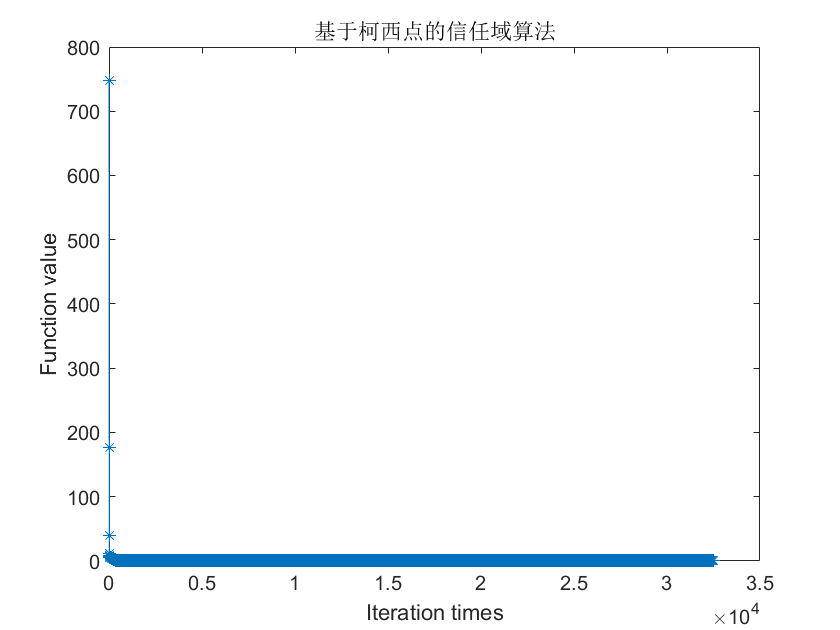

plot(1:1:count+1, fx, '-*');
xlabel('Iteration times');
ylabel('Function value');
title('基于柯西点的信任域算法')

## 2.基于Dogleg的信任域算法

clc;
clf;
tic
[x, fx, count] = TrustRegion(@Rosenbrock, @Dogleg, x0, 2, 0.1, 1e5);
toc

时间已过 12.917137 秒。


x(:, end)

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


fx(end)

ans = 0

count

count = 38

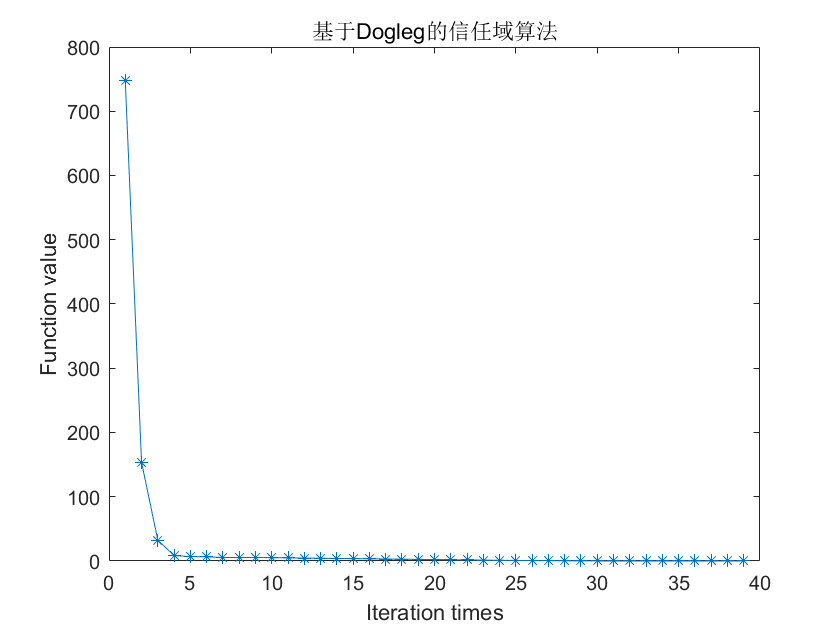

plot(1:1:count+1, fx, '-*');
xlabel('Iteration times');
ylabel('Function value');
title('基于Dogleg的信任域算法')

## 3.基于子问题最优化的信任域算法

clc;
clf;
%x0 = [-1.2;1.2];
tic
[x, fx, count] = TrustRegion(@Rosenbrock, @SubOptimal, x0, 2, 0.1, 1e5);
toc

时间已过 0.017345 秒。


x(:,end)

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


fx(end)

ans = 0

count

count = 103

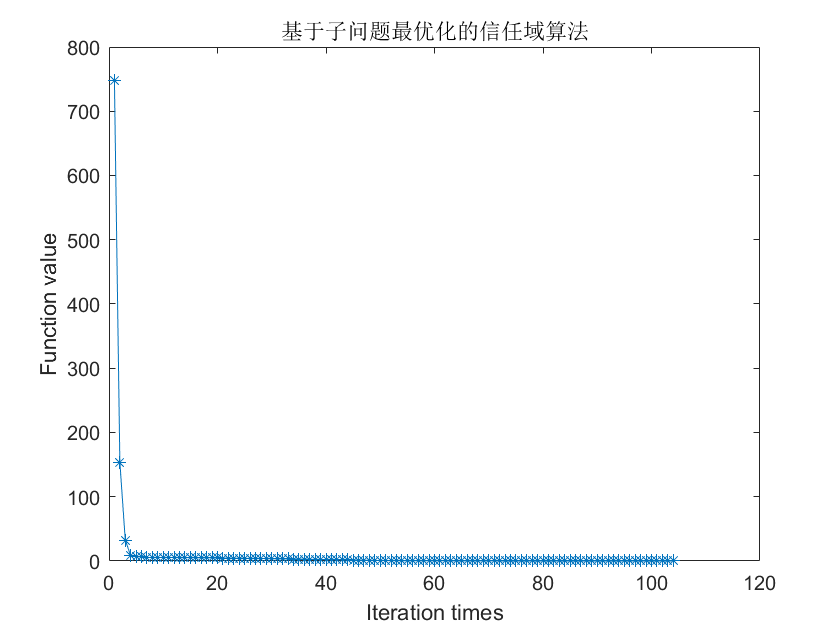

plot(1:1:count+1, fx, '-*');
xlabel('Iteration times');
ylabel('Function value');
title('基于子问题最优化的信任域算法')

## 4.与MATLAB自带函数进行对比

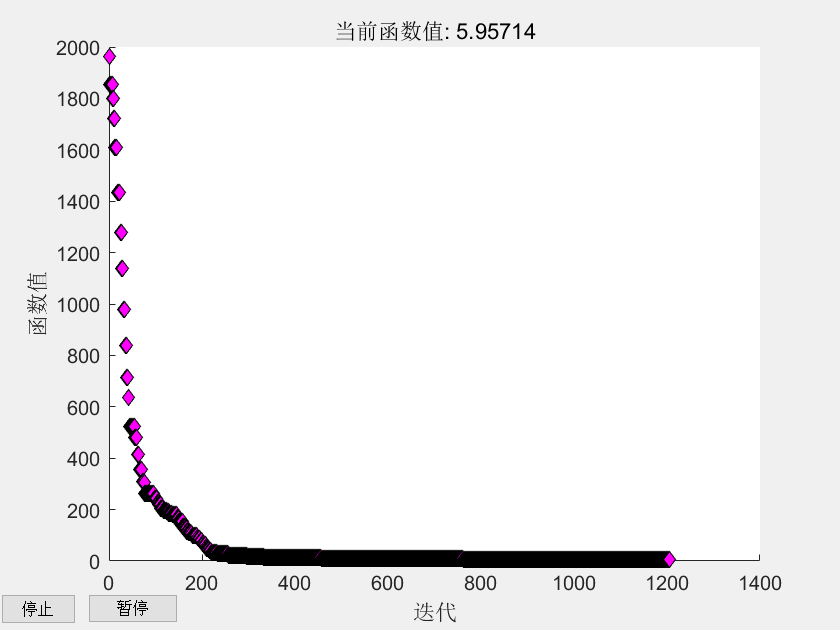

fun = @(x)sum(100.0 * (x(2:end) - x(1:end-1).^2).^2 + (1.0 - x(1:end-1)).^2);
options = optimset('MaxFunEvals', 1e5, 'MaxIter', 1e5, 'PlotFcns',@optimplotfval);
[x, fval, ~, output]  = fminsearch(fun,x0, options);

## 5.信任域算法与线搜索算法下降轨迹对比

## 基于子问题最优化的信任域算法

以下为了绘图方便，考虑二元Rosenbrock函数

clf;
clc;
x0 = [-1.2; 1.2];
[x_tr, fx, count] = TrustRegion(@Rosenbrock, @SubOptimal, x0, 2, 0.1, 1e5);

x_tr(:, end)

ans =      1
     1


fx(end)

ans = 0

count

count = 45

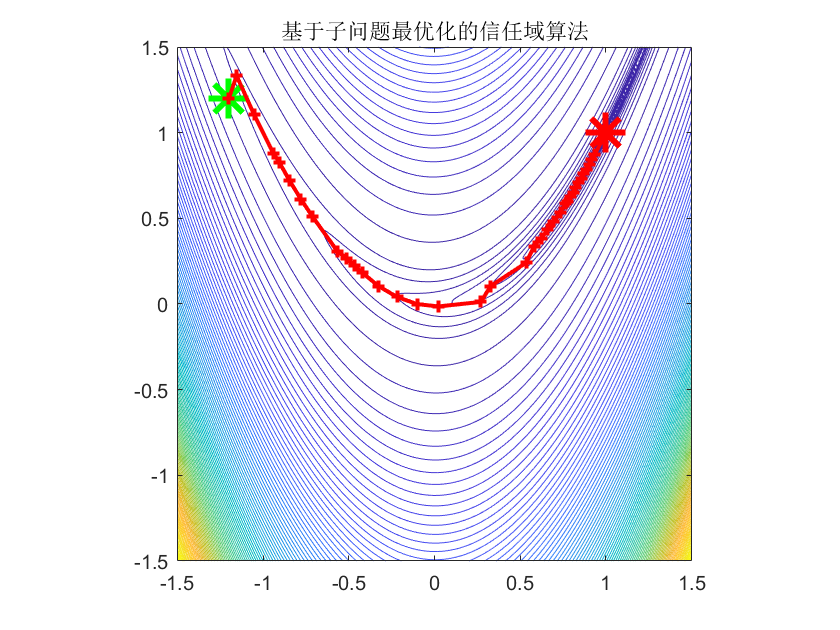

clf;
x = -1.5:0.01:1.5;
y = -1.5:0.01:1.5;
[X, Y] = meshgrid(x, y);
[w, h] = size(X);
vX = reshape(X, 1, w*h);
vY = reshape(Y, 1, w*h);
newX = [vX; vY];
vZ = zeros(size(vX));
for i=1:w*h
    [vZ(i), ~, ~] = Rosenbrock(newX(:, i));
end

figure();
%set(gcf,'Position',[100 100 600 600]);
Z = reshape(vZ, w, h);
contour(X, Y, Z, 100);

v = logspace(-3, 0.7, 15);
hold on;
contour(X, Y, Z, v);
axis equal;

% Target
plot(1, 1, 'r*', 'MarkerSize', 20, 'LineWidth', 3);
% Start
plot(-1.2, 1.2, 'g*', 'MarkerSize', 20, 'LineWidth', 3);

plot(x_tr(1,:), x_tr(2, :), 'r-+', 'LineWidth',2);
title('基于子问题最优化的信任域算法');

## 与线搜索的牛顿法对比

clf;
% 基于回溯法的Newton迭代  
[x_nt, fx, count] = Newton(@Rosenbrock, @BackTracking, x0, 100);
x_nt(:, end)

ans =     1.0000
    1.0000


fx(end)

ans = 1.7810e-20

count

count = 28

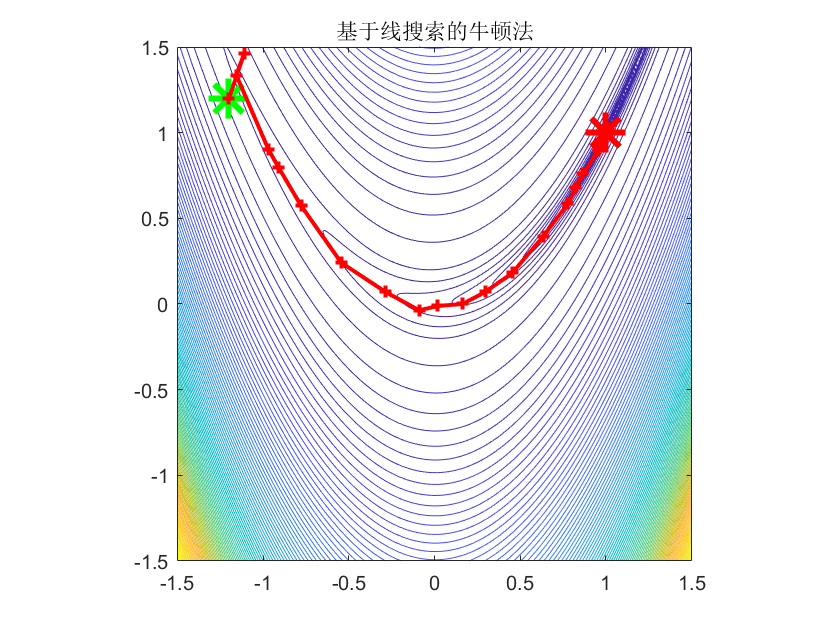

clc;
clf;
x = -1.5:0.01:1.5;
y = -1.5:0.01:1.5;
[X, Y] = meshgrid(x, y);
[w, h] = size(X);
vX = reshape(X, 1, w*h);
vY = reshape(Y, 1, w*h);
newX = [vX; vY];
vZ = zeros(size(vX));
for i=1:w*h
    [vZ(i), ~, ~] = Rosenbrock(newX(:, i));
end

figure();
%set(gcf,'Position',[100 100 600 600]);
Z = reshape(vZ, w, h);
contour(X, Y, Z, 100);

v = logspace(-3, 0.7, 15);
hold on;
contour(X, Y, Z, v);
axis equal;

% Target
plot(1, 1, 'r*', 'MarkerSize', 20, 'LineWidth', 3);
% Start
plot(-1.2, 1.2, 'g*', 'MarkerSize', 20, 'LineWidth', 3);

plot(x_nt(1,:), x_nt(2, :), 'r-+', 'LineWidth',2);
title('基于线搜索的牛顿法');